# Step 1: Reaction Wheel

load('signal_3_12_5.mat');

## Load Data

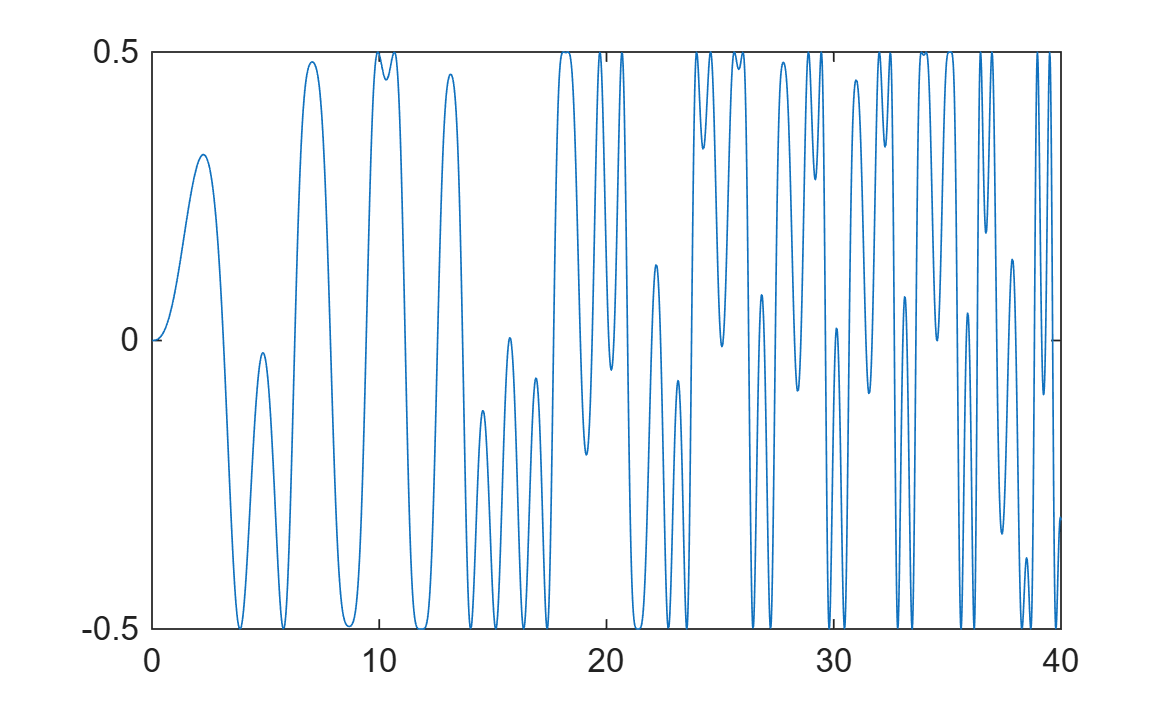

y = angular_velocity.data;
y = y(2:end);
N = size(t,2);
end_train = floor(N*1/2);
figure; 
plot(t,u)

clearvars -except y N t u

## Apply PEM

theta0 = [-5 1000 0.2]';
theta = theta0;
lambda = 0.1;
maxiter = 10000;
p = 3;
h = 0.01;

% initialize
converged = false;
maxiter_reached = false;
iter = 1;
while ~converged && ~maxiter_reached 

    [Abar,Bbar, C,x0] = theta2matrices_phi(theta, h);
    [yhat, xhat] = simsystem(Abar, Bbar, C, x0, u);
    E = y - yhat;
    psi = psi_fun_phi(xhat, x0, Abar, h, u);
    N_E = length(E);
    J = 2/N_E * psi' * E; % Jacobian
    N_H = size(psi,1);
    H = 2/N_H * (psi' * psi); % Hessian

    invLM = (H + lambda * eye(p))\eye(p); %Levenberg-Marquardt singularity inverse
    theta_new = theta - invLM * J;

    
    % Check convergence
    if norm(theta_new - theta) < 1e-6
        converged = true; 
    elseif iter == maxiter 
        maxiter_reached = true; 
        warning('Maximum iterations reached'); 
    end
    theta = theta_new; 
    iter = iter + 1;
end   


## Evaluate

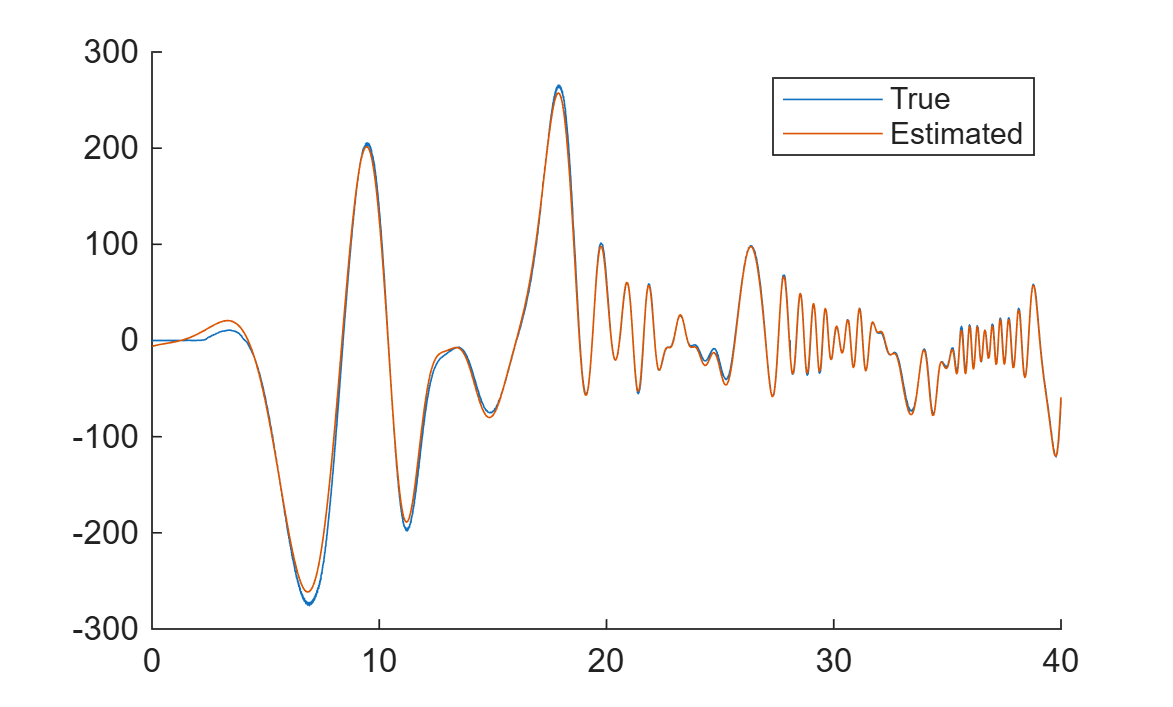

load('signal_3b_12_5.mat')
y = angular_velocity.data;
y = y(2:end);
[yhat, xhat] = simsystem(Abar, Bbar, C, x0, u);

figure;
hold on
plot(t,y);
plot(t,yhat);
legend('True', 'Estimated');


a1 = (1-Abar) / 0.01;
a4 = Bbar(1)/h;

# Part 2 : Pendulum

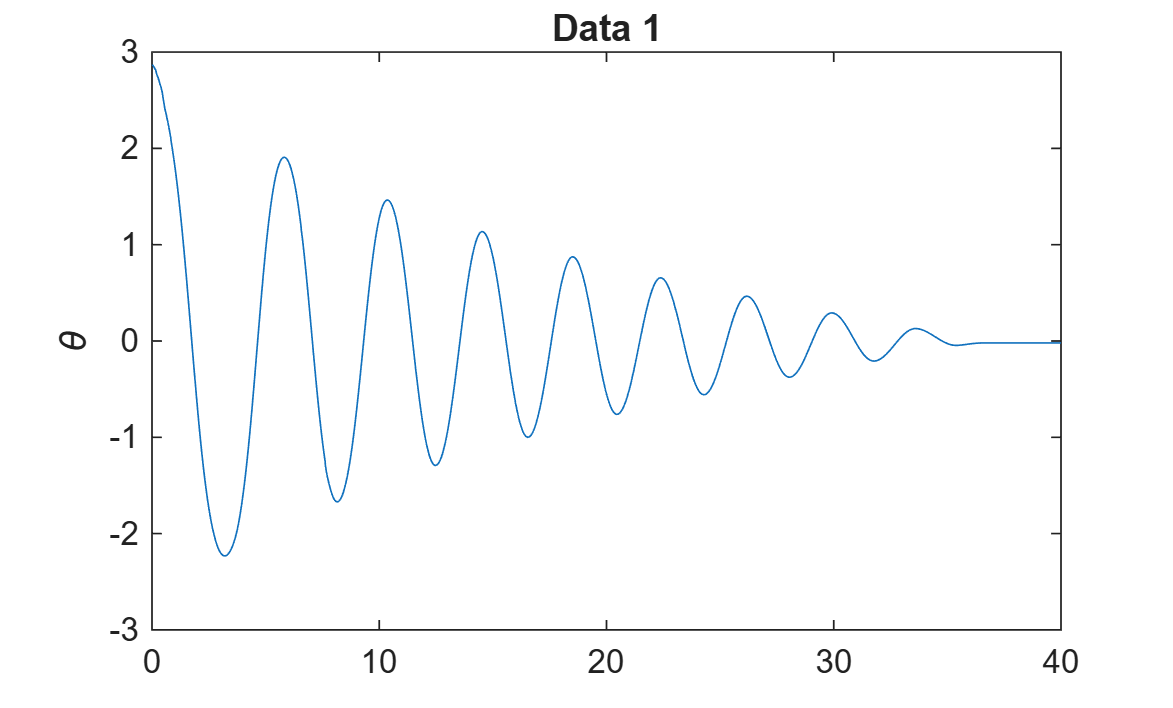

clearvars -except a1 a4
load('signal_2b_12_5.mat')
h = 0.01;
y = pendulum_angle.data;     % theta
y = y(2:end);
N = length(t);
u  = zeros(N,1);

figure;
plot(t,y);
ylabel("\theta")
title("Data 1")

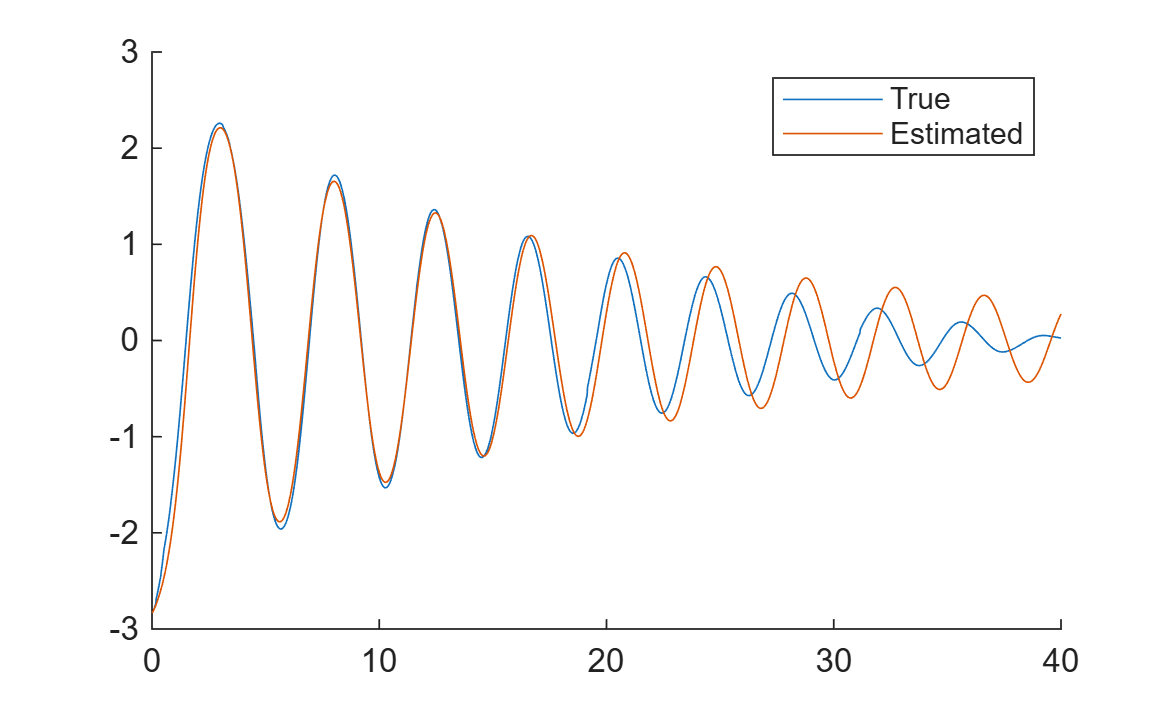



data = iddata(y, u, 0.01);

FileName = 'theta_greybox';
Order = [1 1 2];      % 2 outputs, 1 input, 3 states

Parameters = {
    2.7;    % a3
    0.09;      % a4
    };

InitialStates = [y(1); (y(2)-y(1))/h];
Ts = 0;                % continuous-time model

sys = idnlgrey(FileName, Order, Parameters, InitialStates, Ts);

opt = nlgreyestOptions;
opt.Display = 'on';

sys_est = nlgreyest(data, sys, opt);

a3 = sys_est.Parameters(1).Value;
a4 = sys_est.Parameters(2).Value;

load('signal_2_12_5.mat')
y = pendulum_angle.data;
y = y(2:end);
A = [1 h; -h*a3 1-h*a4];
C = [1 0];
x0 = [y(1); (y(2)-y(1))/h];
N = length(y);

[yhat,~] = simSystem_theta(A,C,x0,N);

figure;
hold on
plot(t,y);
plot(t,yhat);
legend('True', 'Estimated');

# Section 3 : The other bit

clearvars -except a1 a2 a3 a4
